# **ECE 194 Optimization of Engineering Models **

# ***New York City Transit Time Predictions***

# **Professor Mahnoosh Alizadeh**

# **Winter 2020**

# **Andrew Yung**

# **Sansar Yogi**

### **Introduction**

Predicting the estimated time of arrival (ETA) for a car trip has historically always been a challenging problem. Even the best GPS or map services, such as Google Maps, are constantly collecting more data and finding new information to update their algorithms to give better ETA’s. This problem has only seen significantly better solutions rather recently. It wasn’t until 1957 at MIT when scientists started harnessing the Doppler Effect to build the conceptual foundations for GPS. In the late 1980s, full operational GPS satellites started to get launched, and with this new revolution in navigation, technology came increasingly better methods to predict ETA. Still, most of these GPS services were mediocre since they mostly only relied on distances and speed limits to calculate ETAs. Digital mapping services started to become popular in the 2000s, with the first major one - Google Maps - being created in 2005. But even then, the algorithms were not very sophisticated and trip times were often given indecently large intervals. Today, many different services can provide pretty accurate timeframes and can even update continuously during one's trip to account for any changes along the way. In general, this problem of predicting ETA will never see solutions with 100% accuracy since it's impossible to foresee things such as a sudden car crash; however, algorithms get better and better over time. 

For our report, we attempt to solve this problem in New York City, which is unsurprisingly one of the most difficult places in the world to predict ETA because of the dense population and large variation in traffic and other factors out of our control. Aside from the pick-up and drop-off locations, we also consider the day of the week and time of day when calculating the shortest ETA since these tend to be the most important factors. Ideally, we would be able to incorporate factors that other mapping services use such as speed limits, the density of traffic lights, shortest-distance routes, traffic patterns, weather, and much more, but this became infeasible for us due to the extremely high amount of complexity involved. Additionally, it is very difficult to obtain a good set of data necessary just from the internet. We chose to utilize data from past recorded trips, specifically from the NYC Taxi and Limousine Commission throughout the entirety of 2016 with almost 1.5 million data points. The variables recorded include date and time that taxi meters were engaged and disengaged for a trip, the number of passengers, latitude/longitude coordinates of the pick-up and drop-off locations, and the total trip duration (which the data set had already calculated for us). We applied different regression analysis techniques to come up with a final model that would predict the ETA of a trip by car. Although the model would not be perfect, it would be able to inherit the effects and frequency of these uncontrollable factors since the model uses real-life data. In this report, we discuss our mathematical model for performing the regression, along with an alternative model that ultimately did not suit the problem as well. We then show how we pre-processed the data and performed the regression using different subsets of the data for more insight into how the ETA could vary based on the variables recorded in the data. 

#### **Sources:**

[NYC Taxi Limousine Data](https://www.kaggle.com/c/nyc-taxi-trip-duration/data)

[Google Maps Method](https://www.verizonconnect.com/resources/article/google-maps-travel-time/)

[History of GPS](https://www.pcworld.com/article/2000276/a-brief-history-of-gps.html)

[Google Maps Development](https://www.theguardian.com/technology/2015/feb/08/google-maps-10-anniversary-iphone-android-street-view)   

## Mathematical Model

Assumptions: 

- Since NYC is an extremely small section of the Earth, it can be modeled as a plane and a Cartesian coordinate system can be imposed on it with latitude and longitude as the two axes

- The distance from pick-up to drop-off will be calculated by taking the 1-norm of the difference between the pick-up and drop-off coordinates. This choice for distance is based on the fact that most of NYC’s road resemble the Manhattan distance, so to get from one place to another you would only be traveling parallel to lines of latitude and longitude. This way, even if traffic requires you to take different roads, the total distance you travel would still be approximately the same

- Some time durations may not be good representations of the actual time duration due to reasons such as the passenger changing destinations in the middle of the ride, a taximeter being left on longer or shorter than the passenger was in the car, etc. 

- Although the number of passengers for each trip was provided, we chose not to use this factor in our calculations because this would just account for possible distracted driving and carpool lane access. However, all taxis would be able to use such routes since they always have at least 2 people in the car for a given trip and distracted driving would not cause that much of a delay to the trip time.

Variables: 

- Time of pick-up 

- Day of pick-up 

- Distance between pick-up and drop-off 

- Trip duration (seconds)

*Variation in input methods for these variables

Decision Variables: 

- Beta - slope (for the linear regression) 

- alpha - y-intercept of the resulting plane

Constraints: None, since this is a regression problem	

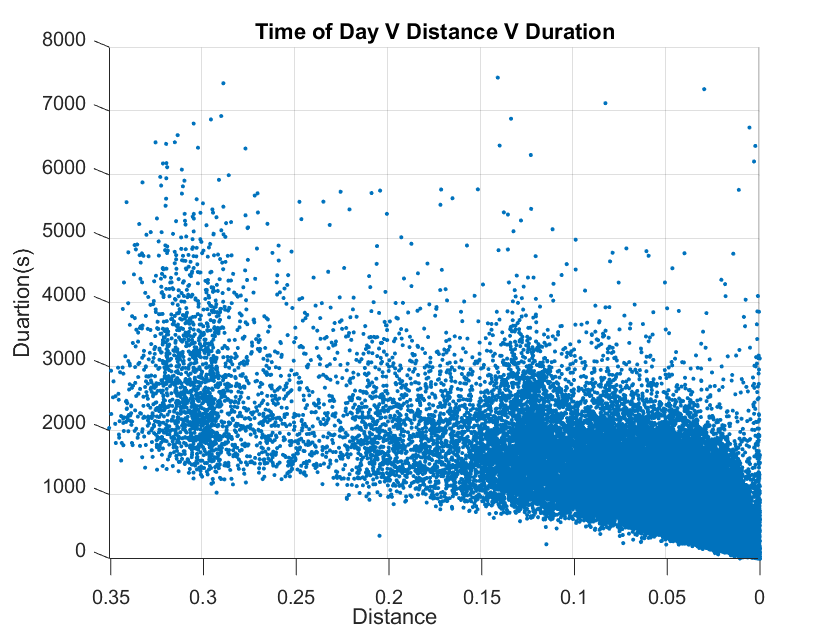

%3D plot Time of Day V Duration V Distance
%RUN to view plot
load('procdata.mat')
isize=84809; %size of matrix without outliers
for i=1:isize
   if procdata(i,51)>0.35
      procdata(i,:)=[]; 
   end
   if procdata(i,52)>8000
        procdata(i,:)=[];
   end
end
%outliers dis> 0.6 && Duration>30,000 taken out

dataplot=zeros(isize,3); %(ToD,Distance, Duration)
for i=1:isize
   for j=1:48
      if procdata(i,j)==1
         dataplot(i,1)=j; %1st column represents which interval out of 48 pick up was
      end
   end
end
dataplot(:,2:3)=procdata(:,51:52);
scatter3(dataplot(:,1),dataplot(:,2),dataplot(:,3),'.')
title('Time of Day V Distance V Duration')
xlabel('Time of Day')
ylabel('Distance')
zlabel('Duartion(s)')

%}

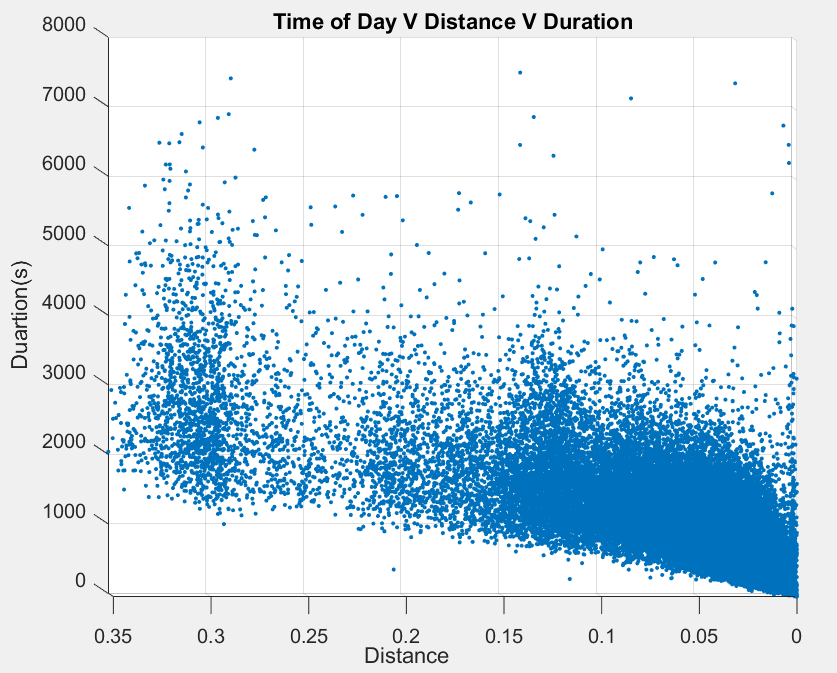

**Figure 1: View of Time vs Distance axis**

From figure 1 we can observe a base line between distance and time with 99% of the points above this line. The points are above this line because the line defines the average speed of travel for without traffic and all of the points above add a certain amount of time dependent on traffic which is also dependent on the time of day. This is why we chose to use a linear model. We found that using other models, such as a cubic model, tended to inflate the model's error and generally stray too far from certain sections of data. 

Objective Function:

Model 1: 

We are using the one norm because traffic congestion is primarily based off of distance and additional time from traffic. If we choose to have distance as our primary prediction method and we know Distance=Speed*Time then we can use the one norm with a multiplied to distance plus another for every specific time interval to account for traffic.

#### 
$$\underset{\alpha ,\beta }{\min \;}$$

$${\left\|T_{\textrm{train}} -\left(x_{\textrm{train}} \beta +\alpha \right)\right\|}_1$$


Model 2:  

We also have the least squares as an option for our model because it is a well-known model that is commonly used. However, with the given data set outliers did have a negative effect on our regression.

#### 
$$\underset{\alpha ,\beta }{\min \;}$$

$${\left\|T_{\textrm{train}} -\left(x_{\textrm{train}} \beta +\alpha \right)\right\|}_2$$


## Solution

Data Processing: 85,000 points instead of 1,458,644 for faster runtime.

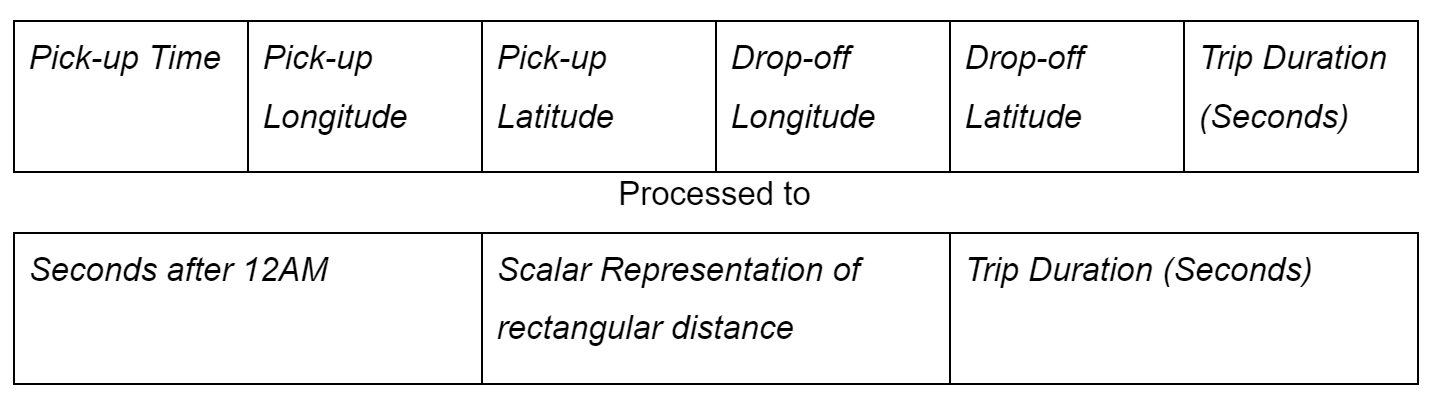

**Table 1:**

**Data Processing: **The given data had to go under heavy processing in order to align with a regression. We found and utilized several matlab functions that helped us manipulate the data. First, the pick-up time was fit into seconds after 12AM of that day so each data point could be categorized into one of 48 30 minute intervals as a binary value. We felt that having 30 minute intervals was safe to assume traffic would not change. The day of the week was fit as a binary value into *Weekday *or *Weekend*. Distance converted to an arbitrary scalar value by adding the magnitudes of $\Delta$Latitude and $\Delta$Longitude. The data was fit into four categories with a total of 52 training variables represented as columns.

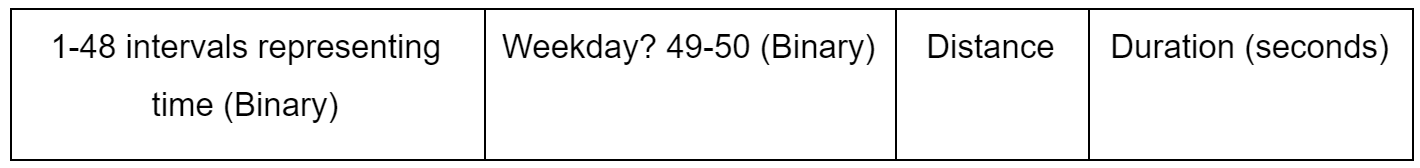

**Table 2:**

The reason we decided to assign binary variables to the time of day and weekday was so when the minimization occurs, only the beta values unique to the time and day would be adjusted accordingly. When the beta array is multiplied, only two beta variables would be adjusted from the time and day for each data point.

**Data Processing**

The following four blocks of code show the data processing that our raw data went under in order to manipulate our data.

These blocks of code take several minutes to run mostly from the *datetime* fuction extraction the day of the week from the given date

%Three segments of coding blocks yielding
%#1 convert extract time of pickup and convert into seconds after midnight 
%#2 Distinguish 0->Weekend 1-> Weekday
%#3 Get the rectangular distance between the two points 
%The training and test error


%convert extract time and convert into seconds after midnight #1
load('Location.mat');
load('Time.mat');
L=Location;
T=Time;
                  
for i=2:85000       %convert time of day into time after 12AM
    d = datetime(T(i,1));
    d.Format = 'hh:mm:ss';
    [Y, M, D, H, MN, S] = datevec(d);
    T(i,3)=H*3600+MN*60+S;
end
%OUTPUT is matrix T Col(1,2,3)=>(Pick_Up Date&time,Date,Time after seconds) 

%Distinguish 0->Weekend 1-> Weekday #2
load('T1.mat');
for j=2:85001
   D=weekday(T1(j,1));
   if D==1||D==7
        T1(j,4)=0;
   else
       T1(j,4)=1;
   end
end
%OUTPUT is matrix T 85000X 4 Col(1,2,3)=>(Pick_Up Date&time,Date,Time after seconds,)

%Get the rectangular distance between the two points #3
load('Location.mat')
L1=Location;
%abs(deltalatitude)-abs(deltalongitude)
for i=2:85001
    lat1=abs(L1(i,1));
    long1=abs(L1(i,2));
    lat2=abs(L1(i,3));
    long2=abs(L1(i,4));
    L1(i,5)=abs(lat1-lat2)+abs(long1-long2);
end
%OUTPUT is matrix T 85000 x 6 (lat1,long1,lat2,long2,'Distance',Duration
%(s)

%DataProcessing1
%Incorporate time of day and weekend/weekday

%Given datetime: Time=> one of 30min 48 intervals, weekday? Var(49),
%weekend? Var(50), Dis=> Var(51)

%go through all points
load('L1.mat')
load('T1.mat')

procdata=zeros(85001,52);       %desired output
procdata(:,51:52)=L1(:,5:6);    %import Distance & Duration into last two columns

for i=2:85001
    val=str2double(T1(i,3));    %observe seconds after day
    
    for j=1:48                  %Time of day assigned to one of 1-48 0,1 var
        lowb=(j-1)*1800;
        highb=j*1800;
        if lowb<val && val<highb
            procdata(i,j)=1;
            location=j;
        end
    end
    
    D=weekday(T1(i,2));
    if D==1 || D==7              %Weekday?
        procdata(i,50)=1;
    else
        procdata(i,49)=1;
    end
end

procdata(1,:)=[];                 %Omit first row with just labels (should have done earlier)

%OUTPUT 85000x 52 matrix
% Col 1-48 48 intervals 30 min ea 1 or zero for data point in that interval?
% 49 Weekday?, 50 Weekend?
% 51 "disatnce" 52 Duration (s)

% Regression.m
load('L1.mat')
load('T1.mat')
%1 Regression Omitting time and day of the week
%2 Regression Focusing on weekdays
%3 Regression Focusing on weekends
trainperc=0.80;
num=1;

%Code format ran one at a time

%ALL DAYS #1
%{
size=85001;
Trows=floor(size*trainperc);

trainset=str2double([T1(2:Trows,4),L1(2:Trows,5:6)]); %Trainset [weekday?, Distance?, Duration]
testset=str2double([T1(Trows+1:size,4) , L1(Trows+1:size,5:6)]);

cvx_begin
    variables a(1) b(2)
    minimize norm(trainset(:,3) -(a(1)+trainset(:,1:2)*b)  ,num)
cvx_end

trainingerror=norm(trainset(:,3) -(a(1)+trainset(:,1:2)*b) , num)/(Trows-1);
disp(trainingerror)
testingerror=norm(testset(:,3) -(a(1)+testset(:,1:2)*b) , num)/(85000-Trows);
disp(testingerror)
%}

%WEEKDAYS ONLY #2
%{
set=str2double([T1(2:85001,4),L1(2:85001,5:6)]);
size1=sum(set(:,1)); %Number of weekdays
dayset=zeros(size1,3);
count=1;
for i=1:85000 % extract only weekday data points
    if set(i,1)==1
        dayset(count,:)=set(i,:);
        count=count+1; 
    end      
end
rows=floor(trainperc*size1);
trainset=dayset(1:rows,2:3); %Trainset [ Distance?, Duration]
testset=dayset(rows+1:size1,2:3);

cvx_begin
    variables a(1) b(1)
    minimize norm(trainset(:,2) -(a(1)+trainset(:,1)*b)  ,num)
cvx_end

trainingerror=norm(trainset(:,2) -(a(1)+trainset(:,1)*b) , 1)/rows;
disp(trainingerror)
testingerror=norm(testset(:,2) -(a(1)+testset(:,1)*b) , 1)/(size1-rows);
disp(testingerror)
%}

%WEEKENDS ONLY #3
%{
set=str2double([T1(2:85001,4),L1(2:85001,5:6)]);
days=sum(set(:,1)); %Number of weekdays
ends=85000-days;
dayset=zeros(85000-days,3); %size of weekends
count=1;

for i=1:85000 % extract only weekend data points
    if set(i,1)==0
        dayset(count,:)=set(i,:);
        count=count+1; 
    end      
end
rows=floor(trainperc*ends);
trainset=dayset(1:rows,2:3); %Trainset [ Distance?, Duration]
testset=dayset(rows+1:ends,2:3);

cvx_begin
    variables a(1) b(1)
    minimize norm(trainset(:,2) -(a(1)+trainset(:,1)*b)  ,num)
cvx_end

trainingerror=norm(trainset(:,2) -(a(1)+trainset(:,1)*b) , 1)/rows;
disp(trainingerror)
testingerror=norm(testset(:,2) -(a(1)+testset(:,1)*b) , 1)/(ends-rows);
disp(testingerror)

%}


%Regression1
%Incorporating time of day weekday and distance (everything)
%Also this took around 15min to run

trainperc=0.80;
num=1;

load('procdata')
A=size(procdata);
size1=A(1,1);
row=floor(trainperc*size1);

trainset=procdata(1:row,:);
testset=procdata(row+1:size1,:);

cvx_begin
    variables a(1) b(51)
    minimize norm(trainset(:,52) -(a(1)+trainset(:,1:51)*b)  ,num)
cvx_end

trainingerror=norm(trainset(:,52) -(a(1)+trainset(:,1:51)*b) , num)/(row);
disp(trainingerror)
testingerror=norm(testset(:,52) -(a(1)+testset(:,1:51)*b) , num)/(size1-row);
disp(testingerror)
%output displayed on table ##

## Results/Discussion

When analyzing the data and looking for patterns our model could work off of we found the following trends with traffic.

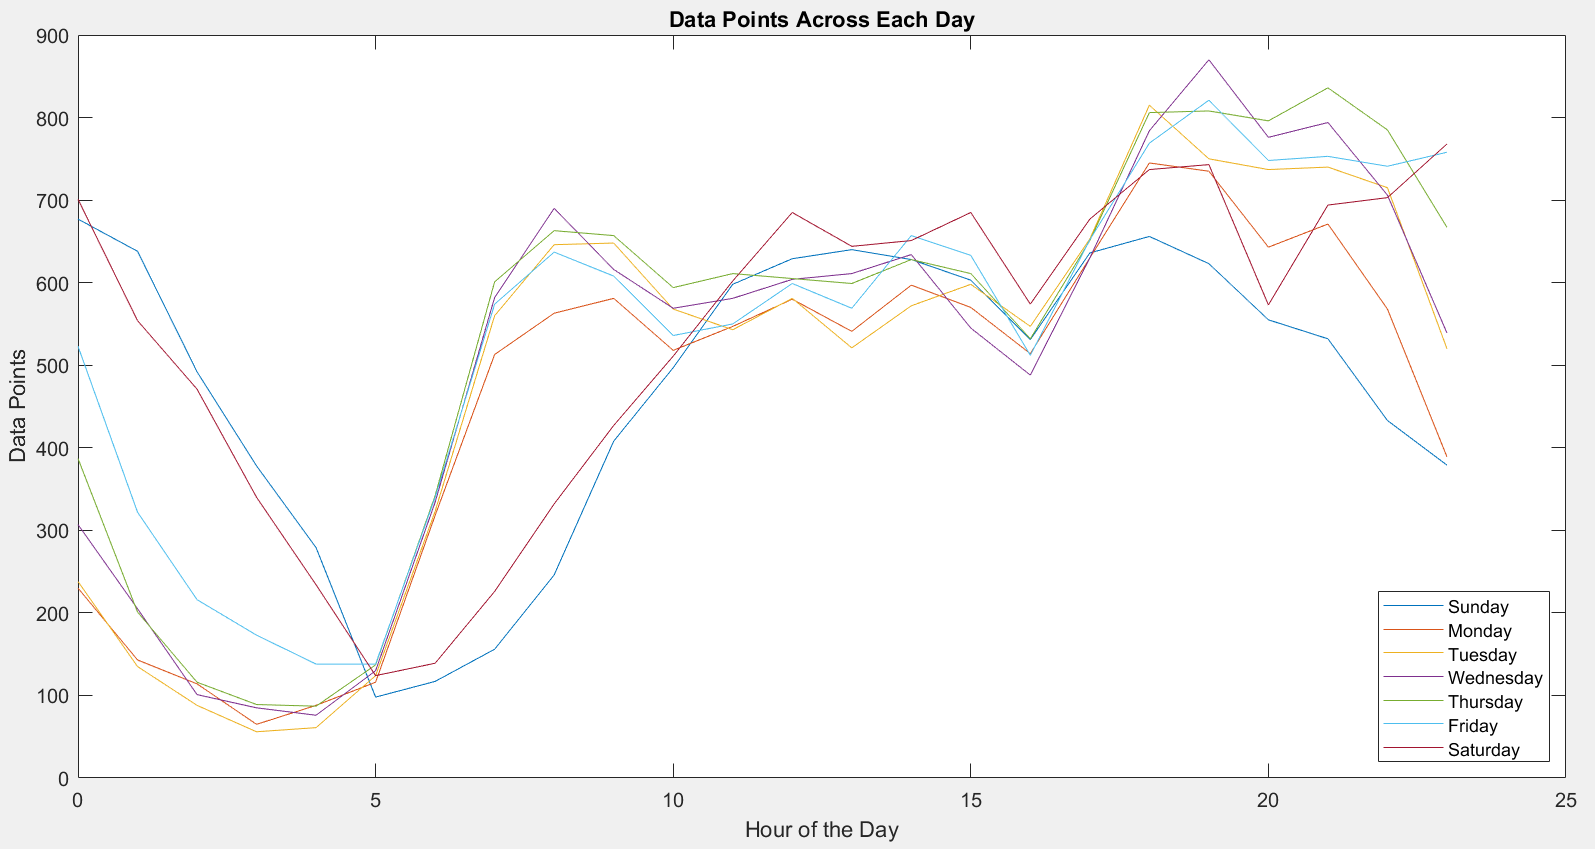

**Figure 2: Data points per hour of each day ***WeekDays.m, Plotdays.m*

When implementing this linear regression with we found these results with this much accuracy.

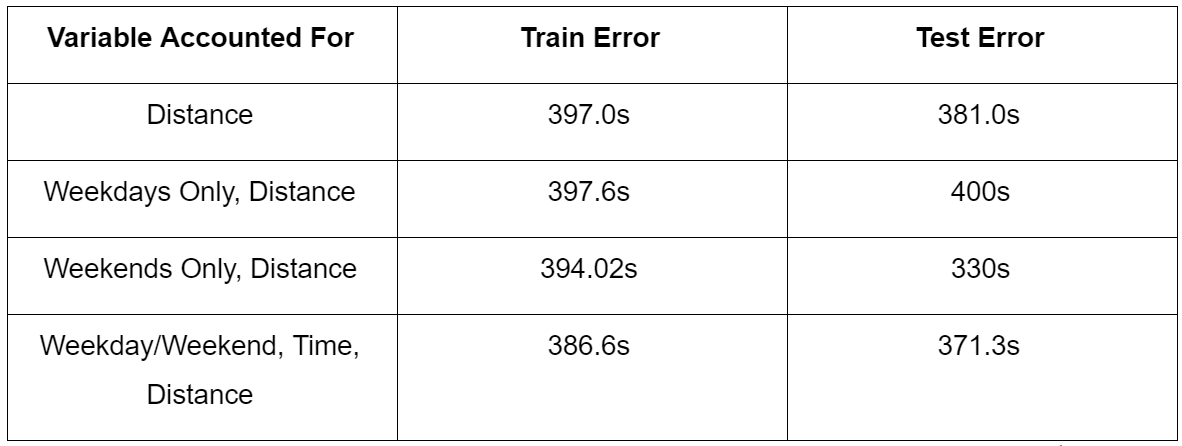

**Table 3: Error Yielded from varying input methods **

*Regression1.m, DataProcessing1.m, Regression.m, Dataprocess.m*

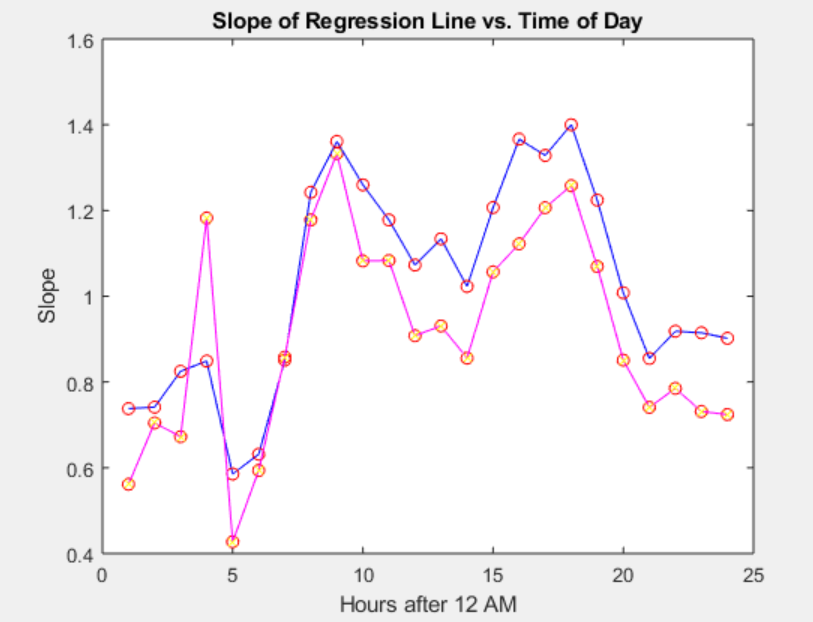

**Figure 3: Plot of Traffic Congestion throughout the day ***Regression2.m*

(purple line represents solutions using 2-norm, blue line using 1-norm)

The figure above plots the calculated betas, or slopes of the regression line, versus the time of day (given in hours after 12 AM). Although this plot doesn’t necessarily help in our original problem of predicting trip time, the plot is useful We chose to do two plots, one using the 1-norm (in blue) and the other using 2-norm (in magenta), so we could see how prominent outliers are in the data. To see why that works, we calculated the average error per entry for both 1-norm and 2-norm (done by taking the expression we are optimizing and dividing by the number of data points). The average error calculated for the 1-norm was 421 seconds, while the average error for the 2-norm was 42.5 seconds. Since the 1-norm is more robust to outliers than the 2-norm, the significantly larger error for 1-norm implies that there are quite a few outliers. However, this large number of outliers is not exactly distributed evenly over the times; there are multiple reasons for these outliers, which will be discussed in the next paragraph.  

Aside from the data points between 1 AM and 6 AM, the curve for 2-norm appears to be mostly the same shape as the one for 1-norm, but shifted down. The 2-norm curves having slopes lower than those for the 1-norm implies that the majority of outliers tended to be outliers in the negative direction. In other words, most of the outliers were outliers because their y-value, the trip time, was smaller than expected. This could be attributed to times during the day where traffic was particularly low for whatever reason, causing trip time to get deflated. This phenomenon seemed to happen more than the opposite case (days with very large traffic) from around 10 AM to 11 PM. However, the two curves don’t really have the same shape at all from 12 AM to 5 AM; we see a random peak of the 2-norm curve at 4 AM. At these times, traffic should not be as much of a consideration. The primary reason for this is most likely due to the fact that we had significantly less data to work with during these times. The random spread of high and low outliers could also be due to mistakes in reporting trip time and other randomly chaotic factors that could happen at these dark hours. At 4 AM, people who go clubbing on the weeknights are spending way too long in the taxis trying to give directions while drunk,or could be experiencing effects from copious amounts of alcohol and taxis are having to wait too long for them. Aside from this whimsical reason, there are probably many other weird things that happen to cause taxi times to inflate a lot in both directions during these times. 

Returning our focus to the general trend of both curves when they are similarly shaped, we can interpret the shape by remembering that beta represents how much time is needed for a trip of a given distance. This plot indicates that beta has two peaks right around 9 AM and 6 PM, implying that trips arounds these time will take longer than usual. This is definitely what we expect, since both of these times are prime traffic hours on weekdays for people heading to and leaving their work. All the other times conform to what we expected; smaller beta’s during night hours than mid-day hours, and - using the 1-norm curve - even smaller in the later hours between 12 AM and 6 AM. 

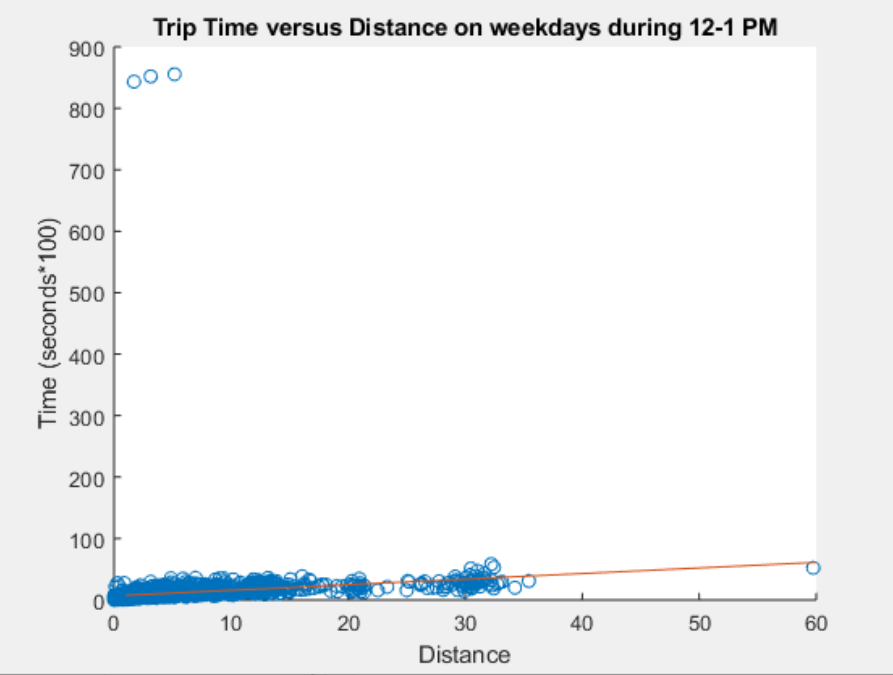

**Figure 4a: Trip Time versus Distance (including 3 major outliers) ***Regression3.m*

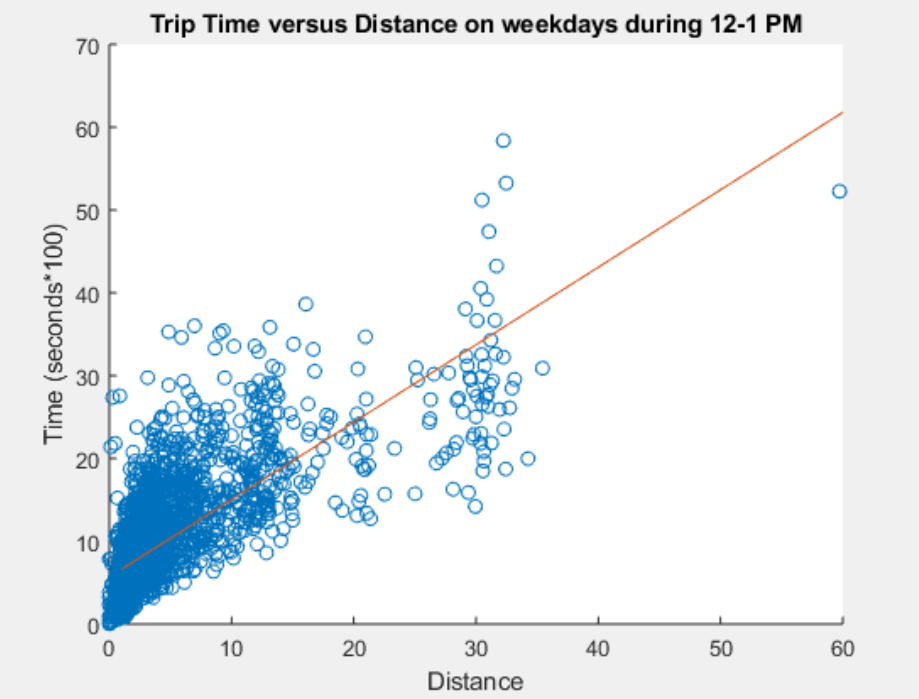

**Figure 4b: Trip Time versus Distance (without the 3 major outliers) ***Regression3.m*

The two plots above show how prominent some of the outliers in the data were, and the major effect they caused. For simplicity, only data from the weekdays and during noon - 1 PM was used. As seen in Figure 2a, the scatter plot mostly resembles a linear trend except for 3 random points that were blown way out of proportion - each one having a trip time that’s at least 20 times larger than all the points below them. Because of how drastically far the outliers were, the reason for these outliers is almost certainly due to a miscalculation or incorrect recording of data from those specific trips, something beyond our control. When we re-plotted the data but replaced the outliers with copies of other points in the data, we obtained a much better looking trend as shown in Figure 2b. Furthermore, our calculations for error showed that the average error per entry went from 454 seconds to 342 seconds, a roughly 25% decrease in error solely due to 3 out of 2831 points. The following two plots show more outliers that affected our regression line for all points on Saturdays.

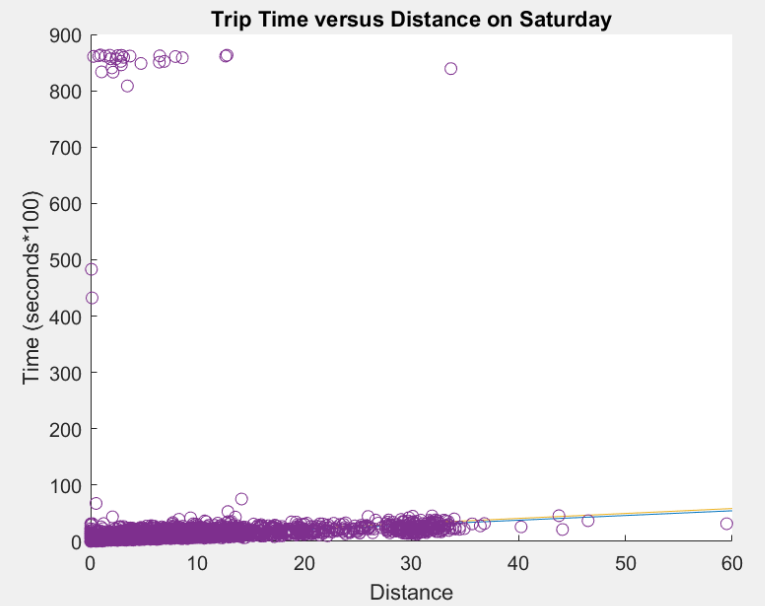

**Figure 5a: Trip Time versus Distance (including 29 major outliers) ***SaturdayDVT.m*

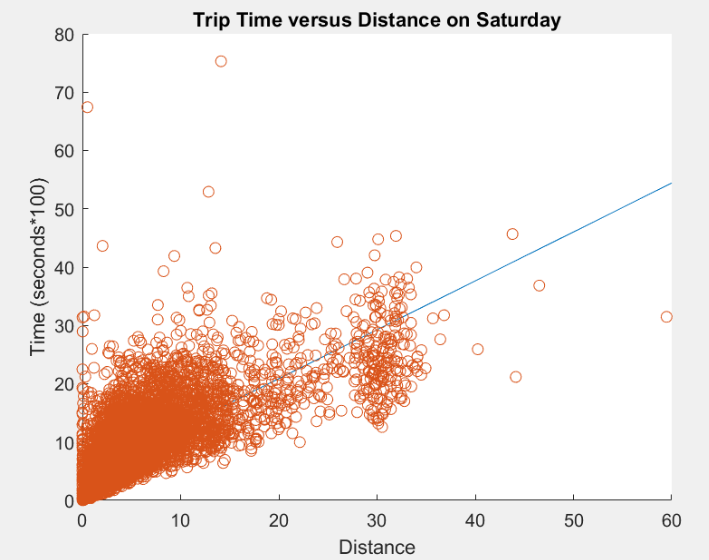

**Figure 5b:Trip Time versus Distance (without the major outliers) ***SaturdayDVT.m*

If we compare the two beta values from figures 4b and 5b which are respectively: $\beta_{\textrm{Weekday}\;12\textrm{PM}} =0\ldotp 93495$,$\beta_{\textrm{Saturday}} =2\ldotp 5462$ we can see that Saturday is significantly more affected by traffic than a weekday at 12PM. This is a reasonable result since a weekday at 12PM has minimal traffic compared to all of Saturday.

## Conclusion

Our original project proposal initially was to output a predicted transit time given a set of coordinates defining pick up and drop off coordinates and the time of day. However, our project veered toward a data analysis of New York City's traffic focused on finding a linear regression to best define the dynamic trends. We went under large amounts of data processing to find the best regression catered around various factors such as time of day, day of the week, and filtered datasets. 

From figures 2 and 3 we can see that the beta values and traffic congestion align similarly. The beta values which indicate the additional amount of time added for the respective time have peaked around 8 AM and 6 PM while figure 2 has peaks around the same times. Figure 2 also represents traffic changes since a peak amount of available data points is associated with high taxi traffic which results in high local traffic in general. This observation reassures us that our regression properly read from the data.

As we can see from figures 4b and 5b, taking the norm of the coordinates in addition to the variations of traffic throughout the day vary duration times drastically from the projected line. In the future, we could work with various models that take in time in a non-linear fashion, because traffic can also increase travel time exponentially. As for the actual travel distance, instead of assuming the NYC is a purely grided street layout, we could find data that finds the shortest distance between the points through NYC. 

Google maps offers it API freely to the public and this tutorial: [Distance Between Two Points](https://www.youtube.com/watch?v=lusad8WirIc)  can teach us how to output the driving distance between two coordinates along with the recommended route. From these finely tuned distance inputs, we would have a more accurate model to predict transit times.